clc;clear;
data1=load('America.txt');%将数据文件以矩阵格式赋给data1
m=length(data1);%计算样本数量
x=data1(:,1);%将第一列数据赋给变量x，注意这里逗号不能少
y=data1(:,2);%将第二列数据赋给变量y
syms theta_0 theta_1;%定义符号变量
%代价函数
J=@(theta_0,theta_1) sum((theta_0+theta_1.*x-y).^2)/(2*m);
%画代价函数的曲面图
a=linspace(-10,20,100);
b=linspace(-5,5,100);
z = zeros(length(a), length(b));%创建代价函数值的二维网络
for i = 1:length(a)
    for j = 1:length(b)
	  z(i,j) = J(a(i),b(j));%注意这里等号右边不可以是J(i,j)
    end
end
z=z';%矩阵求转置
[a,b]=meshgrid(a,b);
subplot(2,2,1)
surf(a,b,z)
title('代价函数曲面图');xlabel('theta_0');ylabel('theta_1');zlabel('J');
shading interp
subplot(2,2,2)
contour(a,b,z,100,'showtext','on')%画等高线图
title('代价函数等高线图')
p0=diff(J,theta_0);%求偏导，几何意义为最快下降路线
p1=diff(J,theta_1);
Alpha=0.01;%定义学习率并初始化为0.01，控制下降速度
theta_0=0;%将theta_0，theta_1全部初始化为0
theta_1=0;
%执行梯度下降算法
for k=1:1500%循环迭代取得theta_0，theta_1的精确值
    %theta_0开始下降，结果存于临时变量
    temp0=theta_0-eval(Alpha*p0);
    temp1=theta_1-eval(Alpha*p1);
    %两个结果同步更新
    theta_0=temp0;
    theta_1=temp1;
end
theta_0

theta_0 =           10.0900788187966


theta_1

theta_1 =          0.533618308019385


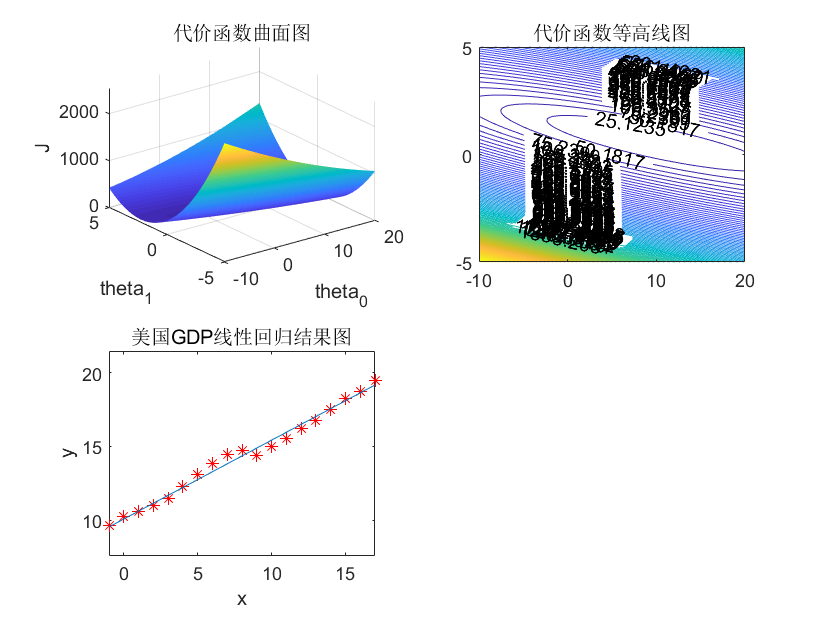

h_theta_A=theta_0+theta_1.*x;
subplot(2,2,3)
plot(x,y,'r*')
hold on
plot(x,h_theta_A)
axis equal
title('美国GDP线性回归结果图');xlabel('x');ylabel('y');